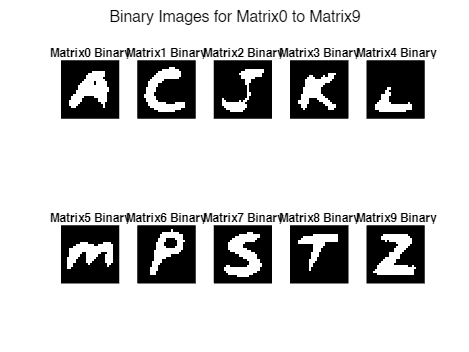

% MATLAB script to read matrix0 to matrix9 from one file
% and plot:
% 1. Binary subplot grid
% 2. Heatmap subplot grid

clc;
clear;
close all;

%% Parameters
filename = 'matrix_output_emnist.txt';
num_matrices = 10;
matrix_size = 784; % 28x28

%% Initialize storage
all_data = zeros(matrix_size, num_matrices);

%% Read file
fid = fopen(filename, 'r');

if fid == -1
    error('Could not open file.');
end

while ~feof(fid)
    line = fgetl(fid);

    % Match format: matrixX[index] = value
    tokens = regexp(line, 'matrix(\d+)\[(\d+)\]\s*=\s*(-?\d+)', 'tokens');

    if ~isempty(tokens)
        matrix_num = str2double(tokens{1}{1}) + 1; % MATLAB indexing
        idx = str2double(tokens{1}{2}) + 1;
        val = str2double(tokens{1}{3});

        all_data(idx, matrix_num) = val;
    end
end

fclose(fid);

%% Binary plots
figure;
for mat = 1:num_matrices
    img = reshape(all_data(:,mat), [28,28])';

    % Individual threshold for each matrix
    threshold = (min(all_data(:,mat)) + max(all_data(:,mat))) / 2;
    binary_img = img > threshold;

    subplot(2,5,mat);
    imagesc(binary_img);
    colormap(gray);
    axis image off;
    title(sprintf('Matrix%d Binary', mat-1));
end

sgtitle('Binary Images for Matrix0 to Matrix9');

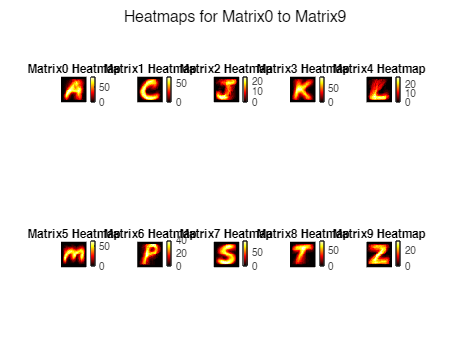


%% Heatmap plots
figure;
for mat = 1:num_matrices
    img = reshape(all_data(:,mat), [28,28])';

    subplot(2,5,mat);
    imagesc(img);
    colormap(hot);
    colorbar;
    axis image off;
    title(sprintf('Matrix%d Heatmap', mat-1));
end

sgtitle('Heatmaps for Matrix0 to Matrix9');

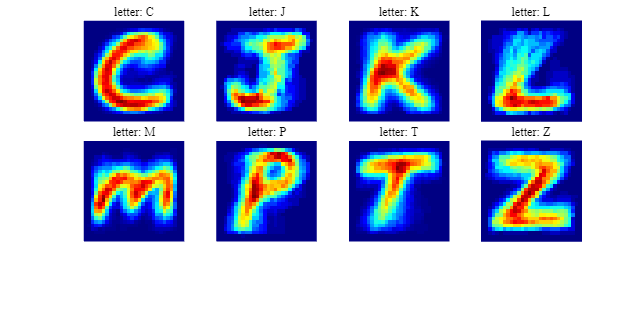


labels = {'0','C','J','K','L','M','P','7','T','Z'};

%% Normalized heatmaps (optional)
figure;

plot_idx = 1;

for mat = 1:num_matrices

    % Skip 1st and 8th images
    if mat == 1 || mat == 8
        continue;
    end

    img = reshape(all_data(:,mat), [28,28])';

    norm_img = (img - min(all_data(:,mat))) / ...
               (max(all_data(:,mat)) - min(all_data(:,mat)));

    subplot(2,4,plot_idx);

    imagesc(norm_img);

    colormap(jet);

    axis image off;
    title(['letter: ', labels{mat}], ...
      'FontSize', 12, ...
      'FontWeight', 'normal', ...
      'FontName', 'Times New Roman');S
    ax = gca;
    pos = ax.Position;

% Make subplot taller
    pos(4) = pos(4) + 0.05;

% Move bottom row upward
    if plot_idx > 4
        pos(2) = pos(2) + 0.10;
    end

    ax.Position = pos;

    plot_idx = plot_idx + 1;

end
set(gcf, 'Units', 'inches');
set(gcf, 'Position', [1 1 8 4]);   % Width=8in, Height=4in

exportgraphics(gcf, 'EMNIST_Normalized_Heatmaps.pdf', ...
               'ContentType', 'vector');